# Air Compressor Fault Detection

Reference paper: [https://ieeexplore.ieee.org/document/7177138](https://ieeexplore.ieee.org/document/7177138)

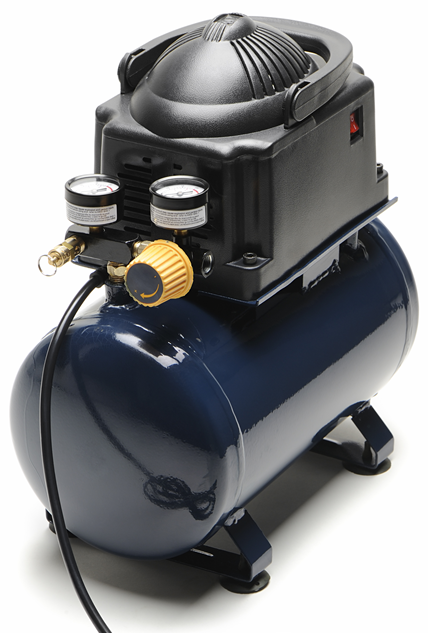

There are seven known faults that can occur with this air compressor, their fault codes are:

In the `AirCompressorDataset` folder there are audio recordings of compressors with each fault listed above as well as a compressor with no faults (healthy).

Each set of recordings is contained in a folder named after the fault code.

In this script you will:

- Import all the audio data using an [`audiodatastore`](https://uk.mathworks.com/help/audio/ref/audiodatastore.html)

- Measure time and frequency domain features of each recording to create a features table

- Train a Machine Learning model using this features table to identify the correct fault code for any audio recording

This script is divided up in to sections, it's recommended that you run each section individually using the **Run Section** button in the toolstrip above.

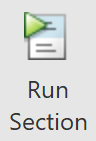

## Pre Work

It is recommended you complete the following on-ramps before proceeding:

  [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted)

  [Machine Learning Onramp](https://matlabacademy.mathworks.com/details/machine-learning-onramp/machinelearning)

## Import Audio Data

First we must import the recordings into MATLAB. For a single file this can be done using the [`audioRead`](https://uk.mathworks.com/help/matlab/ref/audioread.html) function.

Import the first healthy recording

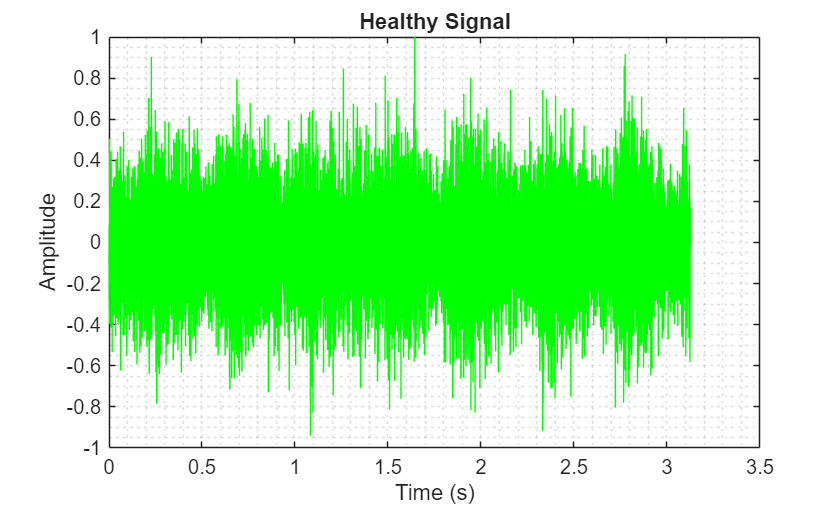

% Add data folder to the MATLAB path - this gives MATLAB access to files in this folder
dataFolder = "AirCompressorDataset";
addpath(genpath(dataFolder))

% Import and play healthy recording
[healthySignal, sampleFreq] = audioread("Healthy\preprocess_Reading1.wav");
sound(healthySignal, sampleFreq)

% Create a time vector for the healthy signal
time = (0:length(healthySignal)-1) / sampleFreq;

% Visualise the signal
figure
plot(time, healthySignal, "green")
title("Healthy Signal")
xlabel("Time (s)")
ylabel("Amplitude")
grid minor

Import the first faulty "Riderbelt" recording

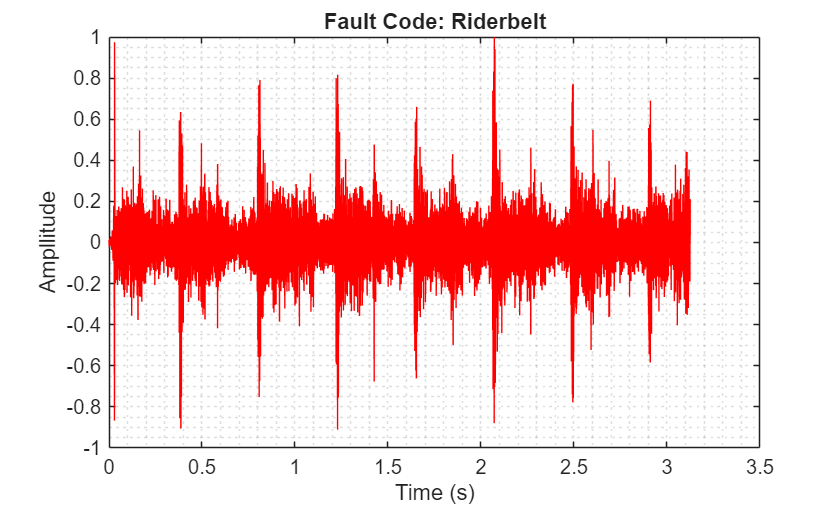

% Import and play unhealthy recording
[unhealthySignal, sampleFreq] = audioread("Riderbelt\preprocess_Reading1.wav");
sound(unhealthySignal, sampleFreq)

% Create a time vector for the healthy signal
time = (0:length(healthySignal)-1) / sampleFreq;

% Visualise the signal
figure
plot(time, unhealthySignal, "red")
title("Fault Code: Riderbelt")
xlabel("Time (s)")
ylabel("Ampllitude")
grid minor

## Create an audio datastore

To import all recordings we will create an audio datastore.

This is a structure which contains information on the audio recordings we want to import, most importantly the filename and fault code label - this is taken from the name of the containing folder.

RecordingsDatastore = audioDatastore(dataFolder,...
    "IncludeSubfolders", true,...
    "LabelSource", "foldernames");

Display filenames

RecordingsDatastore.Files

ans = 1776×1 cell array
    {'C:\Users\pc\Downloads\MathWorks Live Brief\MathWorks Live Brief\AirCompressorDataset\Bearing\preprocess_Reading1.wav'  }
    {'C:\Users\pc\Downloads\MathWorks Live Brief\MathWorks Live Brief\AirCompressorDataset\Bearing\preprocess_Reading10.wav' }
    {'C:\Users\pc\Downloads\MathWorks Live Brief\MathWorks Live Brief\AirCompressorDataset\Bearing\preprocess_Reading100.wav'}
    {'C:\Users\pc\Downloads\MathWorks Live Brief\MathWorks Live Brief\AirCompressorDataset\Bearing\preprocess_Reading101.wav'}
    {'C:\Users\pc\Downloads\MathWorks Live Brief\MathWorks Live Brief\AirCompressorDataset\Bearing\preprocess_Reading102.wav'}
    {'C:\Users\pc\Downloads\MathWorks Live Brief\MathWorks Live Brief\AirCompressorDataset\Bearing\preprocess_Reading103.wav'}
    {'C:\Users\pc\Downloads\MathWorks Live Brief\MathWorks Live Brief\AirCompressorDataset\Bearing\preprocess_Reading104.wav'}
    {'C:\Users\pc\Downloads\MathWorks Live Brief\MathWorks Live Brief\AirCompressorData

Display labels

RecordingsDatastore.Labels

ans = 1776×1 categorical array
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 
     Bearing 


## Extract features from the training dataset

Next we must import each file and extract useful features from the audio data. These features will be used to train a machine learning model to differentiate between fault codes.

Features will include time domain measurements such as:

- **Root mean squared (rms)**

- **Signal-to-noise ratio**

- **Standard deviation**

And frequency domain measurements such as:

- **Peak frequency**

- **Natural frequency**

- **Damping ratio**

Below we use a for loop to move file by file through the dataset. For each file the audio data is imported, features are calculated and saved into a table alongside the label. This is our features table that will be used for training.

% Initialisation steps
numFiles = 1776;

% Create a blank table to hold features information
FeaturesTable = table;

for k = 1:numFiles

    % Import audio data
    [signal, sampleFs] = audioread(RecordingsDatastore.Files{k});

    % Measure features
    features = extractAudioFeatures(signal, sampleFs);

    % Add features to our table
    FeaturesTable(k, :) = features;

end

% Add labels to the table
FeaturesTable.Labels = RecordingsDatastore.Labels(1:numFiles);

% Convert labels to categorical
FeaturesTable.Labels = categorical(FeaturesTable.Labels);

% Display the table
FeaturesTable

FeaturesTable = 1776×11 table
      RMS       SINAD     ShapeFactor    StdDev       SNR      PeakFreq1    PeakFreq2      Wn       Zeta      BandPower    Labels 
    _______    _______    ___________    _______    _______    _________    _________    ______    _______    _________    _______

    0.12122    -12.611      1.3778       0.11732    -12.609     340.93       1648.3      359.33    0.22687    0.0073178    Bearing
    0.16932    -9.9158      1.2795       0.14285    -9.9073     249.54       1660.4      281.98      0.328       0.0141    Bearing
    0.19212    -11.893      1.2847       0.17036    -11.885     253.12 

**TASK: Add Two more time domain features to the **`extractAudioFeatures`** function**

- Run this section.

- You will see that currently the `extractAudioFeatures` function calculates 8 features.

- Add two more time domain features to the function: **standard deviation** and **signal to noise ratio**

- Use the code snippet below to add these features to the `extractAudioFeatures` function.

- Remember to add the calculated values to the output table.

- Re-run this section, if correctly added the features tables should contain 10 features (11 columns).

- Before you proceed update `numFiles` so its value is the total number of files.

- Re-run the section, this will now take approx 6 minutes to run, the feautres table should be size 1776-by-11

## Visualise features

In the step above we converted each audio recording into a set of measurements (features) in the hope that we will be able to use these to distinguish between each fault code group.

A Machine Learning Model will aim to separate each group, by plotting two features we can start to see clusters forming, by considering more features the clusters become more distinct.

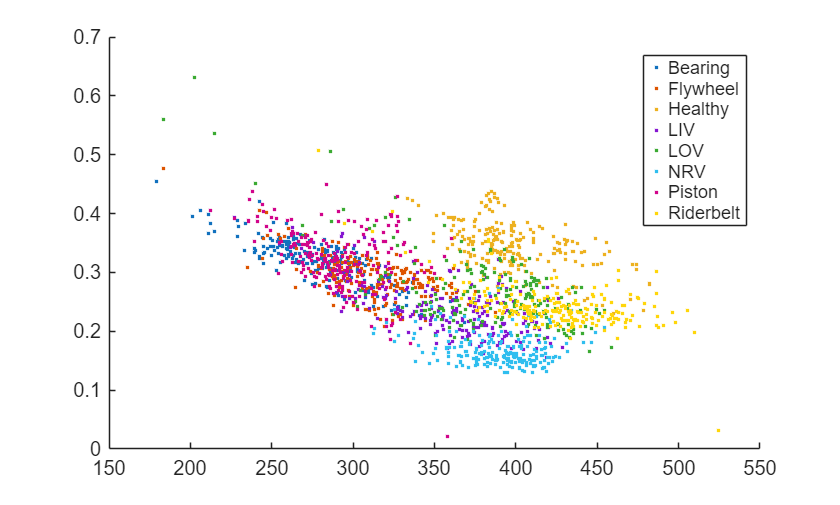

figure
gscatter(FeaturesTable.PeakFreq1, ...
    FeaturesTable.Zeta, ...
    FeaturesTable.Labels)

## TASK: Train a Machine Learning Model

Use the classification learner app to train **three** machine learning models using the features table.

Open the app by running the command below.

classificationLearner

It's important to test the trained models to assess their performance. Do this by setting aside 10% of the features table for testing. 

It's important that we don't test our model using the same data that was used for training.

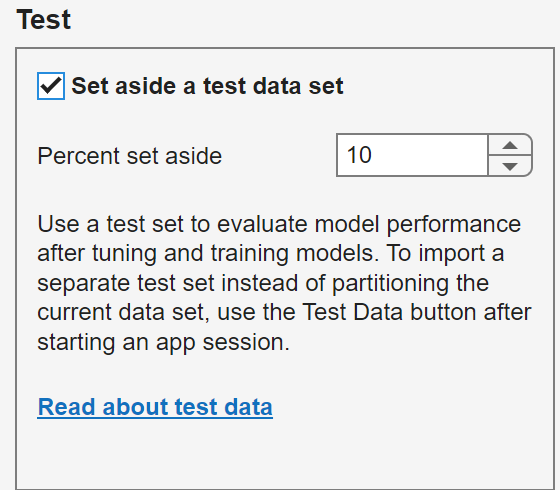

Select a tree model, SVN model and another of your choosing to train.

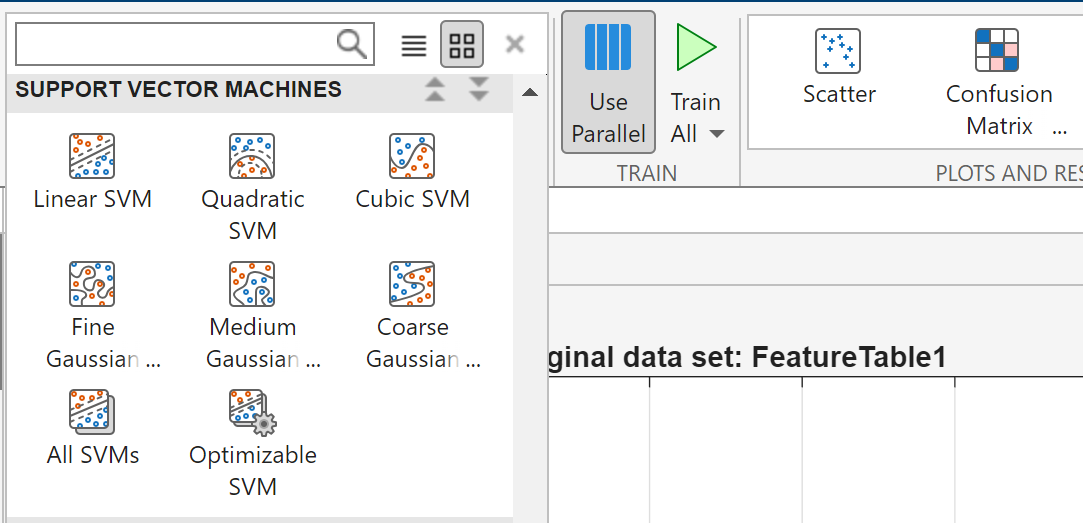

Once training is complete produce a confusion chart **for each model** using the reserved test data.

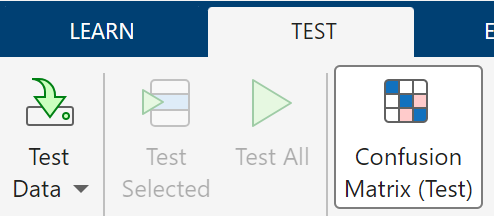

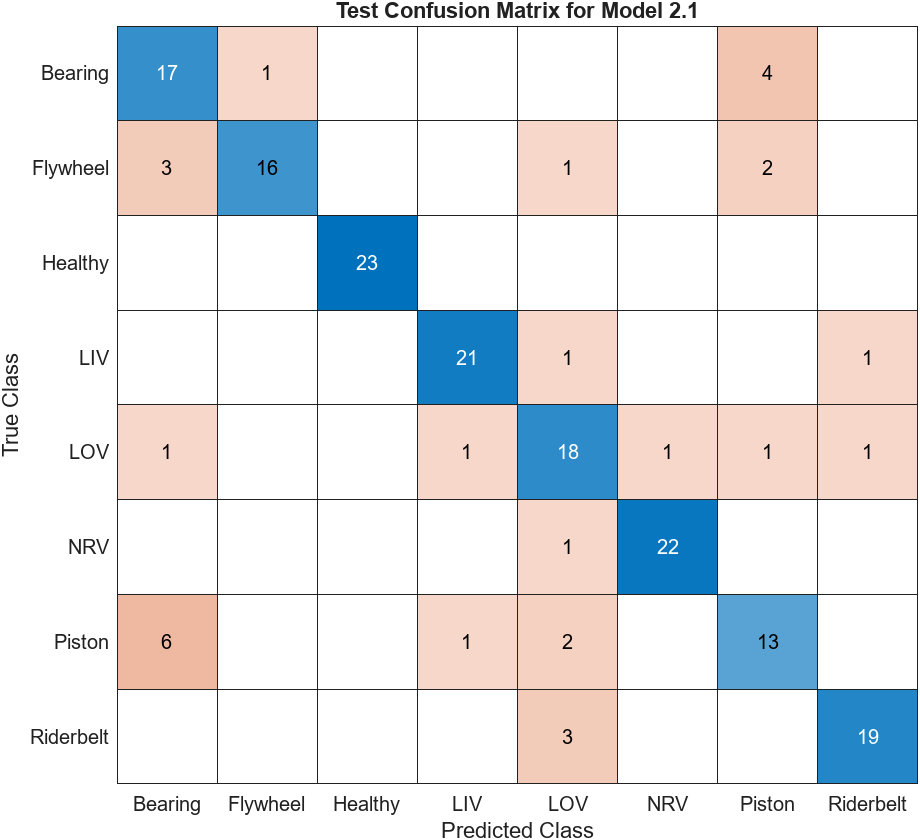

This chart shows how well each model performed for each fault code. Use this to decide which model you will use going forward.

Export your chosen model to the workspace and save it as a .mat file for use later on

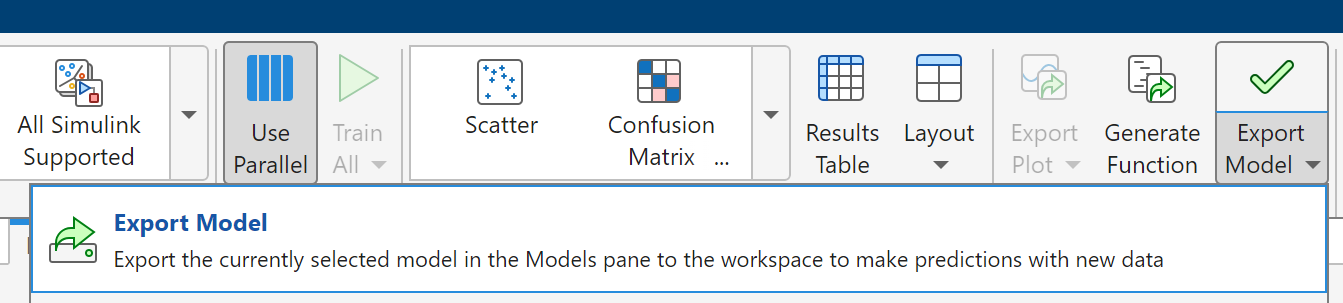

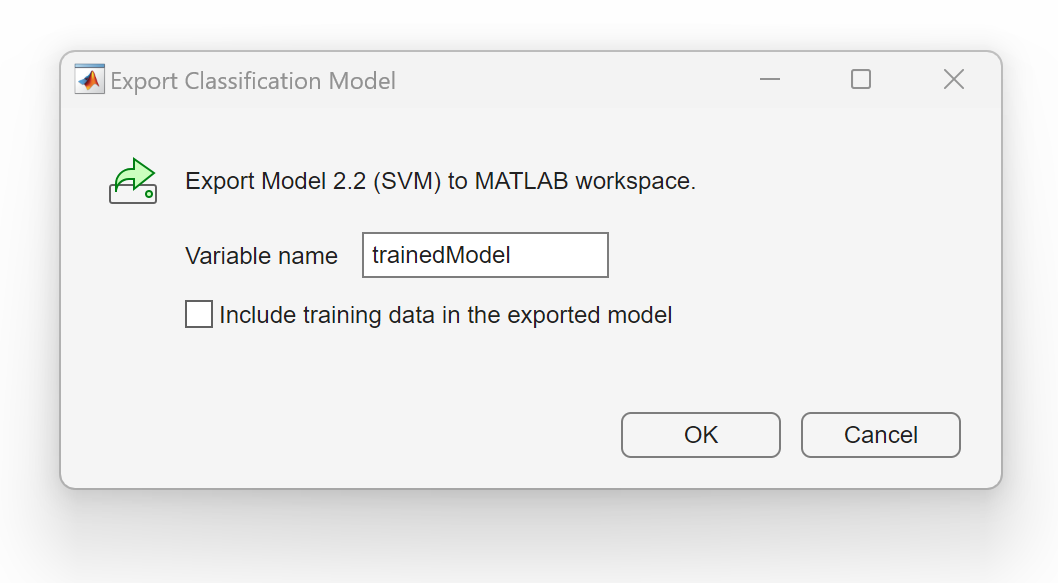

## Making a prediction

You have been provided with some unlabeled audio data in a folder called **U**`nknown_Recordings`

Use the feature extraction function `extractAudioFeatures` and your machine learning model to classify the audio.

% Import audio data into MATLAB
[s, f] = audioread("UnknownRecordings\Unknown_1.wav");

% Extract features

% Pass features to model to make a prediction

**Task: Create fault classification function**

Package this prediction workflow into a standalone MATLAB function.

If you are new to creating functions in MATLAB - learn how to do this here:

[The How and Why of Writing Functions](https://matlabacademy.mathworks.com/details/the-how-and-why-of-writing-functions/otmlhwf)